#### BME 4400 Vanderbilt University

#### Professor Mark D. Does

# Fourier Transforms

This is another big topic that we're only going to touch on briefly. The key idea here is that you can represent a signal (including an image) as a linear combination of complex exponential functions. There are different reasons for doing this, and in this class we'll see how the Fourier Tranform is relevant to both Computed Tomography and Magnetic Resonance Imaging.

First, let's define the continous inverse and forward Fourier Transforms as commonly presented for time-domain signals


$$s(t) = \int_\infty^\infty df\, S(f) \exp\left(i2\pi f t\right)$$


and


$$S(f) = \int_\infty^\infty dt\, s(t) \exp\left(-i2\pi f t\right),$$
 

where $t$ and $f$ have reciprocal units (e.g,. seconds and hertz), so if $t$ measures time (e.g., in seconds), then $f$ measures frequency (e.g., inverse seconds or hertz).

Think of these equations as saying that a** time-domain signal**, $s(t)$ can be represented by a**n infinite sum of complex exponenti**als, $\exp(i2\pi ft)$, weighted by (complex) coefficients, $S(f)$, and vice-versa. By convention, we use the lower case letter ($s$ in this case) to define the time-domain signal and the upper case of the same letter to define the frequency domain signal. We use the same letter for both domains because *these are the same signals, just presented in different domains*!  

### Example: Periodic Saw Tooth Waveform

To appreciate **smoothly varying complex exponential**s can be summed (an infinite sum, mind you) to create dicontinuous signals, consider this example. Don't be concerned with the details of the coding. This is a** Fourier Series calculation,** not a Fourier Transform, per se, but the underlying point is the same -- you can recreate a signal with sharp discontinuities using **a linear combination of complex exponentials **(i.e., sine and cosine functions)! 

clear all
close all
clc

Define periodic sawtooth signal in the time-domain

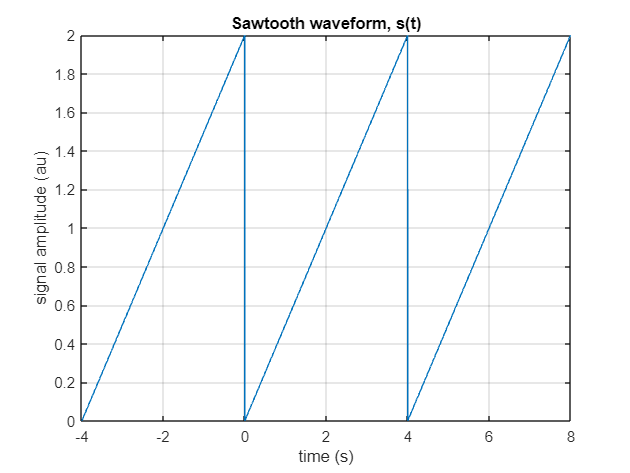

T = 0.001; % sample period
P = 4; % period of signal
t = (0:.001:P-T)'; % one period, for Fourier Series calculation

f0 = 1./P; % lowest frequency needed to reproduce the signal
s = 0.5*t; % sawtooth function over one period
tl = (-P:T:2*P-T)'; % 3 period time domain

figure(1)
plot(tl,[s;s;s],'-')
xlabel('time (s)')
ylabel('signal amplitude (au)')
title('Sawtooth waveform, s(t)')
grid on

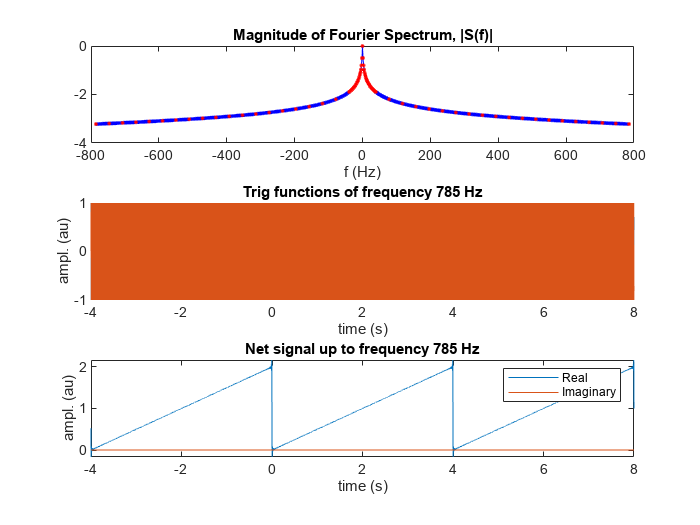

close all
M = 500;
ms = (-M:M)';

clear fe phi Ce
for m = -M:M
    Ce(m+M+1) = 1./P*trapz(t,s.*exp(-1i*2*pi*m*f0*t));
end

f = ms*2*pi*f0;
figure(2), clf
subplot(3,1,1)
plot(f,log10(abs(Ce)),'.-', 'Color','b')
title('Magnitude of Fourier Spectrum, |S(f)|')
xlabel('f (Hz)')
hold on

se = zeros(length(tl),M+1);

for m = 0:M
    se(:,m+M+1) = Ce(m+M+1)*exp(1i*2*pi*m*f0*tl);
    se(:,-m+M+1) = Ce(-m+M+1)*exp(-1i*2*pi*m*f0*tl);
    if (m<25 && m>0) || ~mod(m,25)
        subplot(3,1,1)
        plot(-2*pi*m*f0,log10(abs(Ce(-m+M+1))),'.r',2*pi*m*f0,log10(abs(Ce(m+M+1))),'.r')
        subplot(3,1,2)
        plot(tl,real(exp(1i*2*pi*m*f0*tl)),tl,imag(exp(1i*2*pi*m*f0*tl)))
        xlabel('time (s)')
        ylabel('ampl. (au)')
        title(['Trig functions of frequency ', num2str(2*pi*m*f0,3),' Hz'])
        subplot(3,1,3)
        plot(tl,real(sum(se,2)),tl,imag(sum(se,2)))
        xlabel('time (s)')
        ylabel('ampl. (au)')
        title(['Net signal up to frequency ', num2str(2*pi*m*f0,3),' Hz'])
        legend('Real','Imaginary')
        drawnow
        pause(0.5)
        
    end
end

This animation shows (top) the magnitude of the frequency domain signal spanning approximately ± 800 Hz, (middle) the real and imaginary parts of the complex expoential at one particular frequency, (bottom) the sum of all weighted complex expentials for frequencies up to a certain absolute value. As we include more frequency terms, the sawtooth waveform in the summed signal becomes apparent. 

### Discrete Fourier Transform

We could have a long conversation about the continuous Fourier Transform, but in practice, we work with discretely-sampled signals of finite-duration, so let's forge ahead to the Discrete Fourier Transform (DFT).

Given a discrete-time signal, $s[n]$, $n = 0$ to $n = N-1$, this signal can be represented by a linear combination of complex exponential functions, 


$$s[n] = \frac{1}{N} \sum_{k = 0}^{N-1}S[k]\exp\left(\frac{i2\pi k n}{N}\right)$$


where $S[k]$ is complex (in general). This equation defines what is normally called the inverse DFT (IDFT), and the corresponding forward DFT is


$$S[k] = \sum_{n = 0}^{N-1}s[n]\exp\left(\frac{-i2\pi k n}{N}\right).$$


Here, $n$ and $k$ are just integer values that index time and frequency space, respectively, but you can get back to measures of time and frequency by noting that $t = nT$, where $T$ is the period of time between samples (i.e., between s[n=1] and s[n=2]), and $f = 2\pi k/(NT)$. 

Enough chatter, let's visualize what**'s going on with 1D signals.**

Example 1D, a rectangular pulse. 

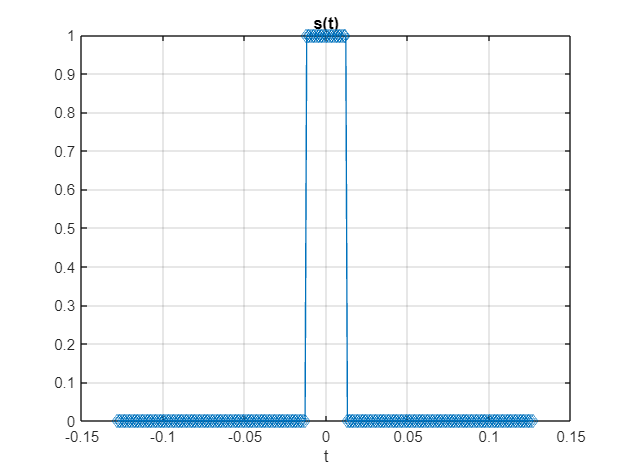

clear all
close all
clc

figure(1)
N = 256;
n = (0:N-1)';
T = 1e-3; % sample period
t = (n-N/2)*T; %
L = 0.025; % width of rect pulse
s = heaviside(-t+L/2)+heaviside(t+L/2)-1;
plot(t,s,'d-'), %axis([-5 5 -0.5 1.25])
xlabel('t'), title('s(t)')
grid on

To compute the DFT, we can perform the sum as defined above, but there's a better way: use th**e Fast Fourier Transform algorith**m. The details aren't important, just know that it calculates the DFT (or IDFT) exactly, just faster. 

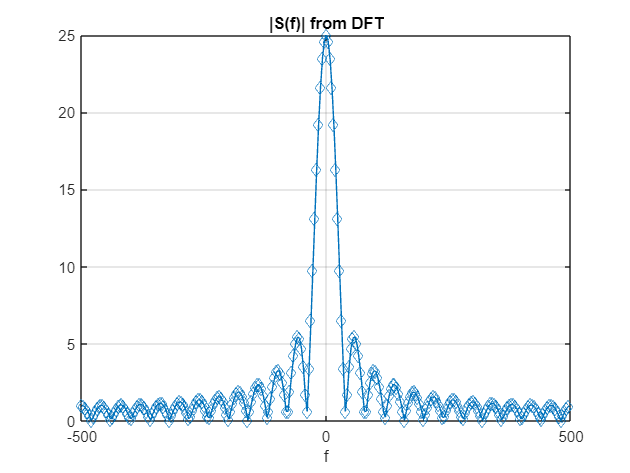

S = fftshift(fft(s));
df = 1./(N*T);
f = (-1/2/T:df:(1/2/T-df))';

figure(2)
% subplot(2,1,1)
plot(f,abs(S),'d-')
xlabel('f'), title('|S(f)| from DFT')
grid on

% subplot(2,1,2)
% plot(f,unwrap(angle(S)),'d-')
% xlabel('f'), title('\angle S(f) from DFT')
% Phase angle of S is not particularly informative

To prove that we can get the original signal bck from its Fourier Transform, we can use the IDFT

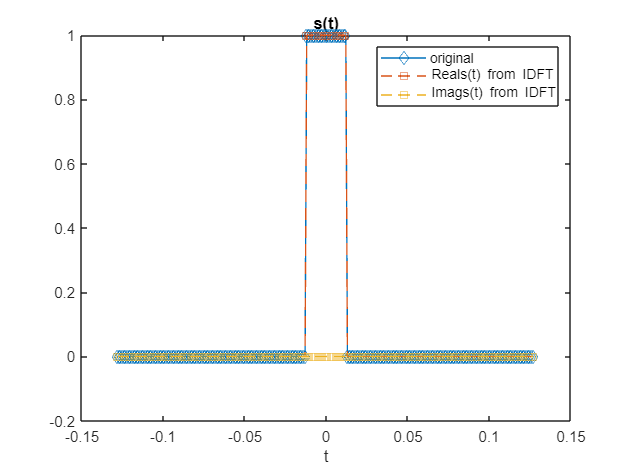

si = ifft(fftshift(S));
figure(3)
plot(t,s,'d-'), %axis([-5 5 -0.5 1.25])
xlabel('t'), title('s(t)')
hold on
plot(t,real(si),'s--',t,imag(si),'s--')
legend('original', 'Real{s(t)} from IDFT', 'Imag{s(t)} from IDFT')

### An imaging example

clear all
close all

Let's use the Shepp-Logan phantom again.

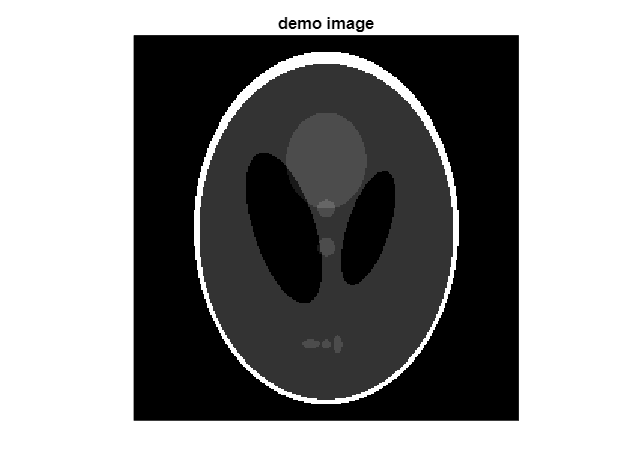

N = 256;
s = phantom(N);
figure(1)
imagesc(s); colormap(gray), axis('equal','off')
title('demo image')

Now compute the 2D Fourier Transform and display the **magnitude spectrum** on a log scale.

Note that `fftshift` simply **moves the center** from frequency space to the center of the matrix.

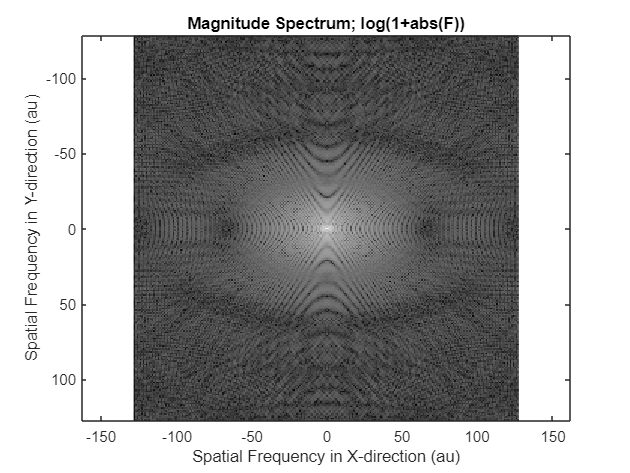

S = fftshift(fft2(s));
figure(2)
f = [-N/2:1:N/2-1];
% imagesc(S); if only do this, super bright spot in middle
% so we need f to scale the visual of FREQUENCY DOMAIN of the signal --->
% ** IN CT/MRI we collect from frequency domain -> transform to time  
imagesc(f,f,log(1+abs(S))); colormap(gray), axis('equal') 
xlabel('Spatial Frequency in X-direction (au)')
ylabel('Spatial Frequency in Y-direction (au)')
title('Magnitude Spectrum; log(1+abs(F))')

#### Reconstruct the Image

In MRI, for example, the observed signal exists in this domain -- the spatial frequency domain. We need t**o collect samples of data in this domai**n and then use the IDFT to reconstruct the image. Aquiring data** further out in frequecy space** results in **a higher resolution **reconstructed image. We can demonstrate this.

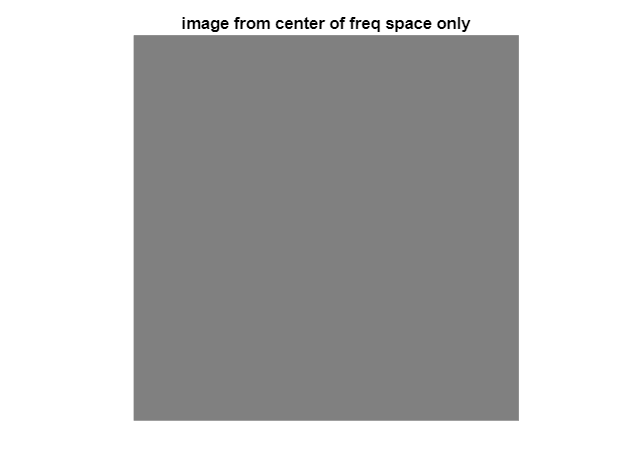

% Build image from the center of the frequency domain out
% center of freq domain is at N/2+1,N/2+1

c = N/2+1; %index of the center of frequency space matrix

% G is a dummy matrix that we'll load up with some of the frequency domain
% information in F
G = zeros(N,N);

% 1st image, take only the CENTER POINT from frequency domain, which
% equates to the "dc-offset" or mean image intensity

G(c:c,c:c) = S(c:c,c:c);
% fftshift back, then do the inverse 2D FFT to get back to image space. In
% general this computation results in complex data, but we know that we
% only want the real part
g = real(ifft2(fftshift(G)));

figure(3)
imagesc(g); colormap(gray), axis('equal','off')
title('image from center of freq space only')

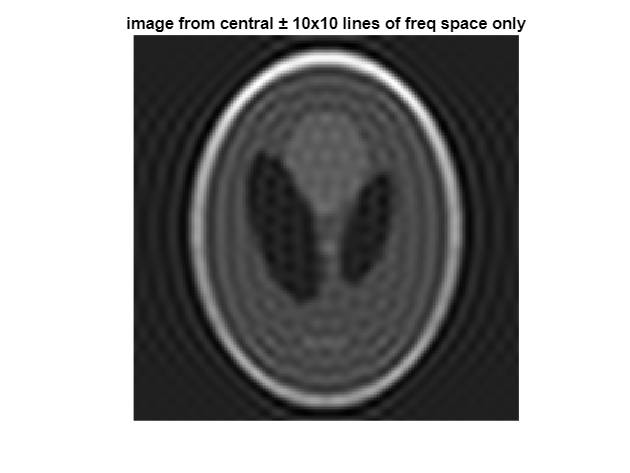

% SUB-SAMPLE
% now try 10 LINES of frequency space surrouding the center ---> BLURRY
% BECAUSE WE PICKED LOW PREQUENCY SINE & COSINE FUNCTIONS
% note that for the image to be real, frequency space must have conjugate
% symmetry, so we need to use an equal number of lines in +ve and -ve freq
% direction

k = 20;

G(c-k:c+k,c-k:c+k) = S(c-k:c+k,c-k:c+k);
g = real(ifft2(fftshift(G)));

figure(4)
imagesc(g); colormap(gray),axis('equal','off')
title('image from central ± 10x10 lines of freq space only')

Note two things**: 1) the image is blurrier than the original, bec**ause it includes only relatively low-frequency information -- i.e., th**e first ±10 lines of frequency space, **and 2) there is a ringing artefact surrounding the head. This comes from **Gibbs ringing,** or **Truncation artefact.** By choosing only the central ± 10 lines of frequency space, we have effectively multiplied the original frequency space signal (F) by a 2D rect function. Multiplication in the frequency domain corresponds to convolution in the image domain, so we have convolved our original image (s(x,y)) with the IDFT of a 2D rect function, which is a 2D sinc function. The oscillatory characteristic of the since function results in the ringing artefact in

the reconstructed image (g(x,y)).

Let's look at how this reconstructed image changes as we vary the amount of frequency domain signal we use in the reconstruction.

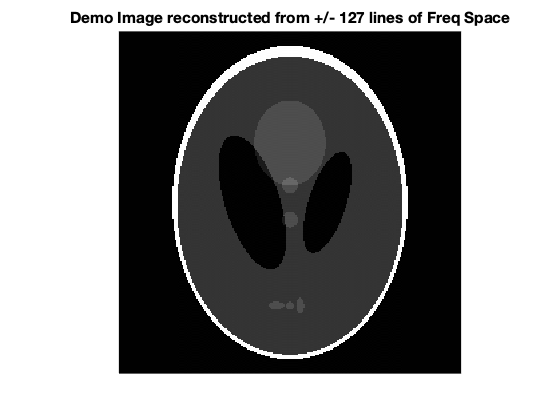


G = zeros(N,N);

for k = 0:127
    G(c-k:c+k,c-k:c+k) = S(c-k:c+k,c-k:c+k);
    g = real(ifft2(fftshift(G)));
    imagesc(g); colormap(gray), axis('equal','off')
    strg = sprintf('Demo Image reconstructed from +/- %d lines of Freq Space',k);
    title(strg)
    if k < 40
        drawnow, pause(.2)
    else
        drawnow
        
    end
end